# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 6*

## Before You Start

In this script you will perform calculations with transfer-functions. In addition to the commands already used, the following MATLAB commands will be used:

- `rlocus,` to plot the root locus of transfer functions

## 6.4 Root-Locus

Construct a transfer-function object with MATLAB's `tf` to represent the linearized car model:

% Linearized car model
pOverBHat = 73.3;
bOverMHat = 0.05;
pOverMHat = pOverBHat * bOverMHat;

G = tf(pOverMHat, [1 bOverMHat])


G =
 
   3.665
  --------
  s + 0.05
 
Continuous-time transfer function.



calculate the loop transfer-function

L = G


L =
 
   3.665
  --------
  s + 0.05
 
Continuous-time transfer function.



to design a proportional controller using MATLAB's `rlocus`:

rl = rlocus(L);

When `rlocus` is called without output arguments it produces a plot as in:

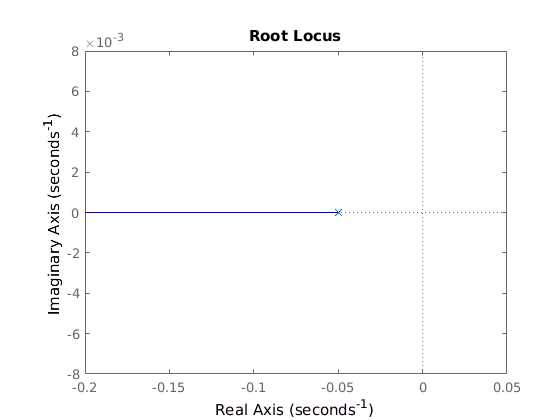

rlocus(L)

Calculate the closed-loop poles for various values of gain:

N = 4;
ks = [0 0.02 0.05 0.5];
mrkrs = {'x', 'd', 's', '^'};

p = {};

i = 1;
p{i} = pole(L);
for i = 2 : N;
  p{i} = pole(feedback(ks(i)*L,1));
end

Plot the combined root-locus with the select closed-loop poles:

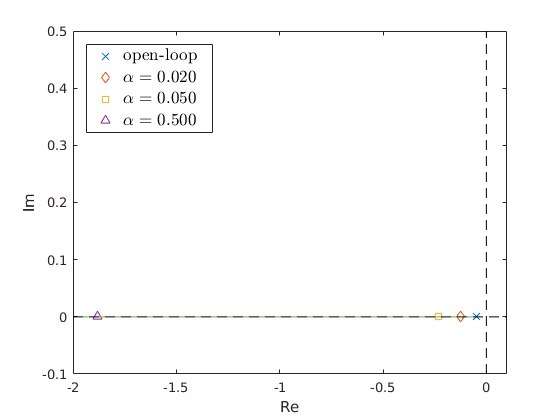

% Fig. 6.10: Root-locus for proportional control
figure()
for i = 1 : N
  plot(real(p{i}), imag(p{i}), mrkrs{i}), hold on
end
xlim([-2, .1])
ylim([-.1, .5])

plot(real(rl'), imag(rl'), ...
     xlim, [0 0], 'k--', ...
     [0 0], ylim, 'k--')
hold off

leg = [char(ones(N, 1) * double('$\alpha = ')) num2str(ks', '%4.3f') char(ones(N, 1) * double('$~~'))];
leg(1,1:9) = 'open-loop';
leg(1,10:end) = ' ';
legfnt = 13;

h = legend(leg,'Location','NorthWest');
set(h, 'interpreter', 'latex', 'FontSize', legfnt);
xlabel('Re')
ylabel('Im')

Calculate the loop transfer-function to design an integral controller:

K = tf(1, [1 0]);
L = K*G;

and evaluate the root-locus and select closed-loop poles:

N = 4;
ks = [0 0.002 0.005 0.05];

rl = rlocus(L);
p = {};

i = 1;
p{i} = pole(L);
for i = 2 : N;
  p{i} = pole(feedback(ks(i)*L,1));
end

Plot the combined root-locus with the select closed-loop poles:

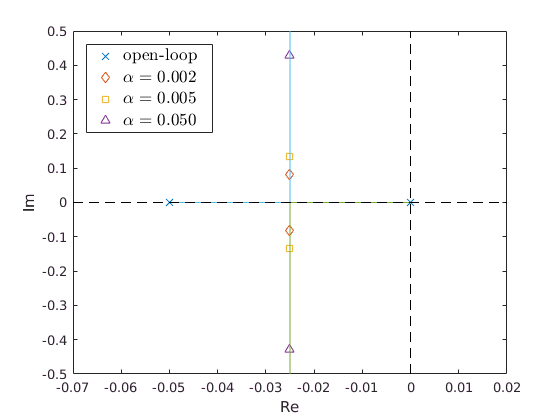

% Fig. 6.12: Root-locus for integral control
figure()
for i = 1 : N
  plot(real(p{i}), imag(p{i}), mrkrs{i}), hold on
end
xlim([-.07, .02])
ylim(.5*[-1, 1])

plot(real(rl'), imag(rl'), ...
     xlim, [0 0], 'k--', ...
     [0 0], ylim, 'k--')
hold off

leg = [char(ones(N, 1) * double('$\alpha = ')) num2str(ks', '%4.3f') char(ones(N, 1) * double('$~~'))];
leg(1,1:9) = 'open-loop';
leg(1,10:end) = ' ';

h = legend(leg,'Location','NorthWest');
set(h, 'interpreter', 'latex', 'FontSize', legfnt);
xlabel('Re')
ylabel('Im')

Calculate the loop transfer-function and evaluate a PI controller with inexact pole-zero cancellation. The value of $\gamma$ represents the mismatch. $\gamma$ = 1 is a exact match.

% Root locus PI control with inexact pole zero cancelation
gamma = [2 1.1 1 0.5];
M = length(gamma);

rl = {};
pz = {};;
alpha = 0.1;

for i = 1 : M

  Kp = 0.1;
  Ki = gamma(i) * Kp * bOverMHat;
  K = tf([1 Ki/Kp], [1 0]);
  L = K*G;
 
  rl{i} = rlocus(L);
  pz{i,1} = pole(L);
  pz{i,2} = zero(L);
  pz{i,3} = pole(feedback(alpha*L,1));

end

Plot the results root-loci for each value of mismatch:

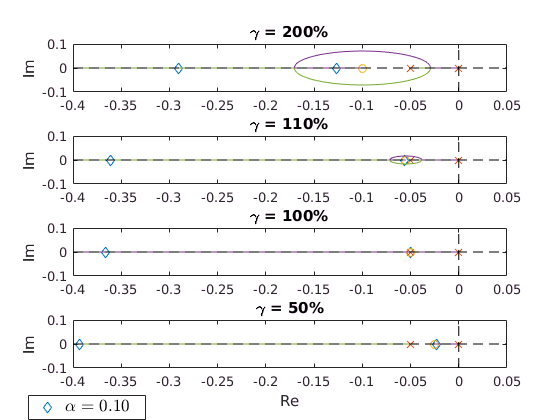

% Fig. 6.14:
figure()
for i = 1 : M

  subplot(M,1,i)

  xlim(2.5*[-.16, .02])
  ylim(.1*[-1, 1])

  plot(real(pz{i,3}), imag(pz{i,3}), 'd', ...
       real(pz{i,1}), imag(pz{i,1}), 'x', ...
       real(pz{i,2}), imag(pz{i,2}), 'o', ...
       real(rl{i}'), imag(rl{i}'), ...
       xlim, [0 0], 'k--', ...
       [0 0], ylim, 'k--')
  title(['\gamma = ' num2str(gamma(i)*100) '%'])
  xlim([-.4, .05])
  ylim([-.1, .1])

  if (i == M)
    xlabel('Re')
    leg = ['$\alpha = ' num2str(alpha, '%3.2f') '$~~'];
    hleg = legend(leg, 'Location', 'SouthWest');
    set(hleg, 'interpreter', 'latex', 'FontSize', legfnt, ...
        'Position', [0.09 0.03 0.13 0.00])
  end
  ylabel('Im')

end

## 6.5 Control of the Simple Pendulum - Part I

Set up pendulum parameter:

m = 0.5

m = 0.5000

l = 0.3

l = 0.3000

r = l/2

r = 0.1500

b = 0

b = 0

g = 9.8

g = 9.8000

J = m*l^2/12

J = 0.0038

Jr = (J+m*r^2)

Jr = 0.0150

and calculate the model linearized around the stable equilibrium:

G0 = tf(1/Jr, [1, b/Jr, m*r*g/Jr])


G0 =
 
   66.67
  --------
  s^2 + 49
 
Continuous-time transfer function.



and evaluate the natural frequency and damping-ratio:

den0 = G0.den{1};
wn0 = sqrt(den0(3)/den0(1))

wn0 = 7

zeta0 = den0(2)/(2*wn0*den0(1))

zeta0 = 0

A convinient way to do that is using MATLAB's damp command:

damp(G0)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 7.00e+00i     0.00e+00       7.00e+00           Inf       
  0.00e+00 - 7.00e+00i     0.00e+00       7.00e+00           Inf       


Repeat for the model linearized around the stable equilibrium:

Gpi = tf(1/Jr, [1, b/Jr, -m*r*g/Jr])


Gpi =
 
   66.67
  --------
  s^2 - 49
 
Continuous-time transfer function.



Evaluate the natural frequency and damping-ratio:

denpi = Gpi.den{1};
wnpi = sqrt(-denpi(3)/denpi(1))

wnpi = 7

zetapi = denpi(2)/(2*wnpi*denpi(1))

zetapi = 0

or using `damp`:

damp(Gpi)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.00e+00     1.00e+00       7.00e+00         1.43e-01    
  7.00e+00    -1.00e+00       7.00e+00        -1.43e-01    


Design a PD controller as in Section 6.2 to set the closed-loop $\omega_n \approx 9.9$ under unit feedback:

Kp = 3*m*r*g

Kp = 2.2050

Kd = 2*sqrt(m*r*g*Jr)-b

Kd = 0.2100

z = Kp/Kd

z = 10.5000


ctrPD = Kp + Kd * tf([1 0],1)


ctrPD =
 
  0.21 s + 2.205
 
Continuous-time transfer function.



zpk(ctrPD)


ans =
 
  0.21 (s+10.5)
 
Continuous-time zero/pole/gain model.



and evaluate the closed-loop performance around the unstable equilibrium point:

H = feedback(ctrPD*Gpi,1)


H =
 
    14 s + 147
  ---------------
  s^2 + 14 s + 98
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.00e+00 + 7.00e+00i     7.07e-01       9.90e+00         1.43e-01    
 -7.00e+00 - 7.00e+00i     7.07e-01       9.90e+00         1.43e-01    


Use `damp` to return the damping ratio and natural frequency:

[wn,zeta] = damp(H)

wn =     9.8995
    9.8995


zeta =     0.7071
    0.7071


wn = wn(1)

wn = 9.8995

zeta = zeta(1)

zeta = 0.7071

Build a loop transfer-function:

L = ctrPD*Gpi;

to visualize the design around the unstable equilibrium point on a root-locus diagram:

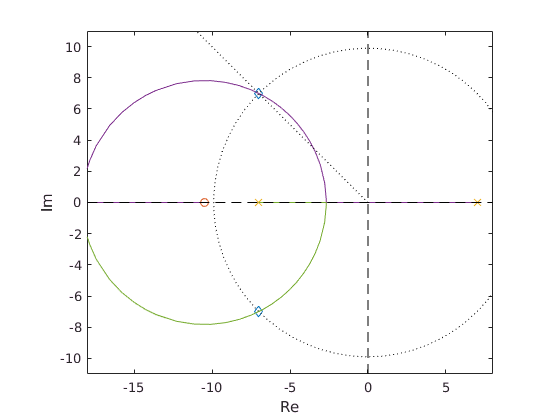

% Fig. 6.15
figure()
t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

H = feedback(L,1);
[wncl,zetacl,pz{3}] = damp(H);

rl = rlocus(L);

xl = [-18,8];
yl = [-11,11];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(1)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

The diamond shows the location of the selected closed-loop poles.

Evaluate the closed-loop performance around the stable equilibrium point as well:

H = feedback(ctrPD*G0,1)


H =
 
     14 s + 147
  ----------------
  s^2 + 14 s + 196
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.00e+00 + 1.21e+01i     5.00e-01       1.40e+01         1.43e-01    
 -7.00e+00 - 1.21e+01i     5.00e-01       1.40e+01         1.43e-01    


Attempt to incorporate integral action to the above proportional-derivative controller by adding a pole at zero:

ctrPDI = ctrPD * tf(1,[1 0])


ctrPDI =
 
  0.21 s + 2.205
  --------------
        s
 
Continuous-time transfer function.



zpk(ctrPDI)


ans =
 
  0.21 (s+10.5)
  -------------
        s
 
Continuous-time zero/pole/gain model.



modify the loop transfer-function as in:

L = ctrPDI*Gpi;

and plot the root-locus:

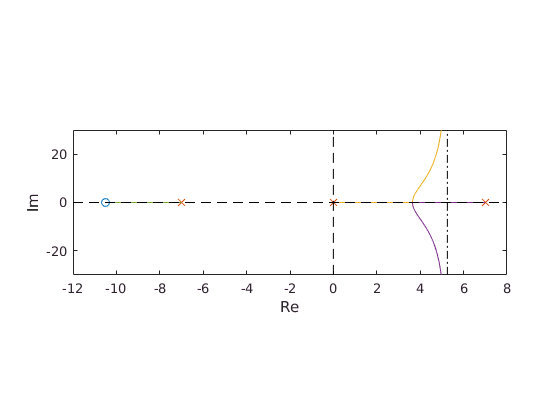

% Fig. 6.16
figure()
pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

rl = rlocus(L);

xl = [-12,8];
yl = [-30,30];

a = (sum(pz{1}) - sum(pz{2}))/(3-1); % center of asymptotes

plot(real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), ...
     a*[1 1], yl, 'k-.', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(xl)/diff(yl) 1]);

that reveals that no positive stabilizing gain is possible.

Attempt to make the PD controller proper by adding a pole far away to the left of the complex plane, in this case 8 times bigger than the value of the zero:

pd = 8*zero(ctrPD)

pd = -84

ctrPDP8 = 0.9*ctrPD*tf(-pd,[1 -pd])


ctrPDP8 =
 
  15.88 s + 166.7
  ---------------
      s + 84
 
Continuous-time transfer function.



zpk(ctrPDP8)


ans =
 
  15.876 (s+10.5)
  ---------------
      (s+84)
 
Continuous-time zero/pole/gain model.



The gain 0.9 places two poles at $\omega_n \approx 9.9$ under unit feedback.

Modify the loop transfer-function:

L = ctrPDP8*Gpi


L =
 
      1058 s + 1.111e04
  --------------------------
  s^3 + 84 s^2 - 49 s - 4116
 
Continuous-time transfer function.



evaluate the closed-loop performance around the unstable equilibrium point:

H = feedback(L,1)


H =
 
       1058 s + 1.111e04
  ----------------------------
  s^3 + 84 s^2 + 1009 s + 6997
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.40e+00 + 7.57e+00i     6.45e-01       9.91e+00         1.56e-01    
 -6.40e+00 - 7.57e+00i     6.45e-01       9.91e+00         1.56e-01    
 -7.12e+01                 1.00e+00       7.12e+01         1.40e-02    


and plot the root-locus:

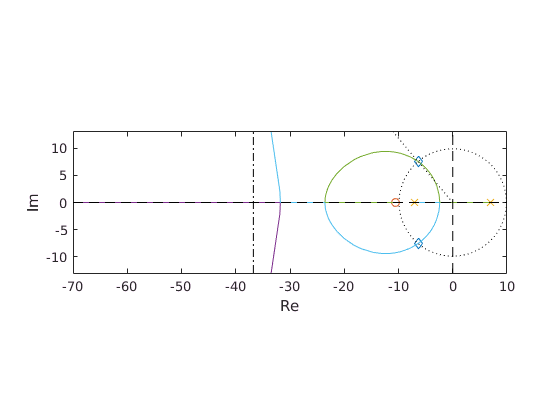

% Fig. 6.17 (a): Place pole 8 times farther than zero
figure()
pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

[wncl,zetacl,pz{3}] = damp(H);

rl = rlocus(L);

a = (sum(pz{1}) - sum(pz{2}))/(3-1); % center of asymptotes

t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

xl = [-70,10];
yl = [-13,13];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), ...
     a*[1 1], yl, 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(1)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

Repeat the above design this time with the pole only two times greater than the zero:

pd = 2*zero(ctrPD)

pd = -21

ctrPDP2 = 0.8*ctrPD * tf(-pd,[1 -pd])


ctrPDP2 =
 
  3.528 s + 37.04
  ---------------
      s + 21
 
Continuous-time transfer function.



zpk(ctrPDP2)


ans =
 
  3.528 (s+10.5)
  --------------
      (s+21)
 
Continuous-time zero/pole/gain model.



The gain 0.8 places two poles at $\omega_n \approx 9.9$ under unit feedback.

Modify the loop transfer-function:

L = ctrPDP2*Gpi


L =
 
        235.2 s + 2470
  --------------------------
  s^3 + 21 s^2 - 49 s - 1029
 
Continuous-time transfer function.



evaluate the closed-loop performance around the unstable equilibrium point:

H = feedback(L,1)


H =
 
         235.2 s + 2470
  -----------------------------
  s^3 + 21 s^2 + 186.2 s + 1441
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.01e+00 + 9.33e+00i     3.07e-01       9.80e+00         3.33e-01    
 -3.01e+00 - 9.33e+00i     3.07e-01       9.80e+00         3.33e-01    
 -1.50e+01                 1.00e+00       1.50e+01         6.67e-02    


and plot the root-locus:

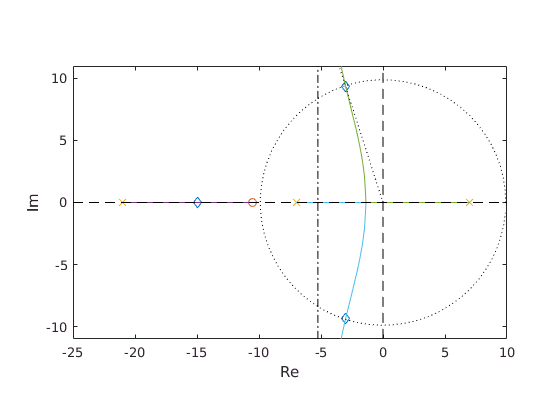

% Fig. 6.17 (b): Place pole 2 times farther than zero
figure()
pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

[wncl,zetacl,pz{3}] = damp(H);

rl = rlocus(L);

a = (sum(pz{1}) - sum(pz{2}))/(3-1); % center of asymptotes

t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

xl = [-25,10];
yl = [-11,11];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), ...
     a*[1 1], yl, 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(1)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

Keep the pole two times greater than the zero but adjust the zero to improve damping:

pd = 2*zero(ctrPD)

pd = -21

ctrPDD = 0.9*Kp*tf([1.4*Kd/Kp 1],1)/1.45;
Clead = ctrPDD * tf(-pd,[1 -pd])


Clead =
 
  5.557 s + 41.67
  ---------------
  1.45 s + 30.45
 
Continuous-time transfer function.



zpk(Clead)


ans =
 
  3.8321 (s+7.5)
  --------------
      (s+21)
 
Continuous-time zero/pole/gain model.



The gain places two poles at $\omega_n \approx 9.9$ under unit feedback.

Modify the loop transfer-function:

L = Clead*Gpi


L =
 
             370.4 s + 2778
  -------------------------------------
  1.45 s^3 + 30.45 s^2 - 71.05 s - 1492
 
Continuous-time transfer function.



evaluate the closed-loop performance around the unstable equilibrium point:

H = feedback(L,1)


H =
 
             370.4 s + 2778
  -------------------------------------
  1.45 s^3 + 30.45 s^2 + 299.4 s + 1286
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.01e+00                 1.00e+00       9.01e+00         1.11e-01    
 -5.99e+00 + 7.91e+00i     6.04e-01       9.92e+00         1.67e-01    
 -5.99e+00 - 7.91e+00i     6.04e-01       9.92e+00         1.67e-01    


and plot the root-locus:

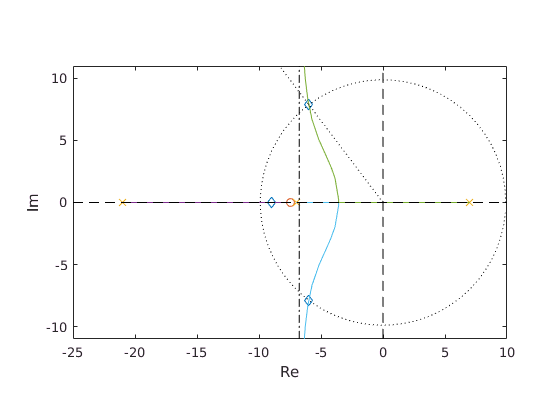

% Fig 6.19: Place pole 2 times and adjust zero
figure()
pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

H = feedback(Clead*Gpi,1);
[wncl,zetacl,pz{3}] = damp(H);

rl = rlocus(L);

a = (sum(pz{1}) - sum(pz{2}))/(3-1); % center of asymptotes

t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

xl = [-25,10];
yl = [-11,11];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), ...
     a*[1 1], yl, 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(2)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

Verify that the design also stabilizes the simple pendulum around the stable equilibrium by modifying the loop transfer-function:

L0 = Clead*G0;

evaluating the closed-loop performance around the stable equilibrium point:

H0 = feedback(L0,1)


H0 =
 
             370.4 s + 2778
  -------------------------------------
  1.45 s^3 + 30.45 s^2 + 441.5 s + 4270
 
Continuous-time transfer function.



damp(H0)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.42e+01                 1.00e+00       1.42e+01         7.05e-02    
 -3.41e+00 + 1.40e+01i     2.37e-01       1.44e+01         2.93e-01    
 -3.41e+00 - 1.40e+01i     2.37e-01       1.44e+01         2.93e-01    


and visualizing the root-locus simultaneously for both stable and unstable equilibria:

% Fig. 6.20: root locus for stable equilibrium
figure()
pz0 = {};
pz0{1} = pole(L0);
pz0{2} = zero(L0);

[wn0cl,zeta0cl,pz0{3}] = damp(H0);

rl0 = rlocus(L0);

a0 = (sum(pz{1}) - sum(pz{2}))/(3-1) % center of the asymptotes

a0 = -6.7500

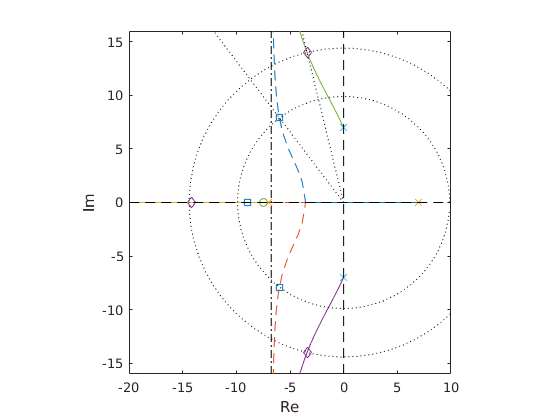


xl = [-20,10];
yl = [-16,16];

plot(real(pz{3}), imag(pz{3}), 's', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(pz0{3}), imag(pz0{3}), 'd', ...
     real(pz0{2}), imag(pz0{2}), 'o', ...
     real(pz0{1}), imag(pz0{1}), 'x', ...
     real(rl'), imag(rl'), '--', ...
     real(rl0'), imag(rl0'), '-', ...
     a0*[1 1], yl, 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     (wn0cl(2)/wn)*real(circ), (wn0cl(2)/wn)*imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(2)))], 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zeta0cl(2)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

Evaluate and plot the frequency response of the controllers so far:

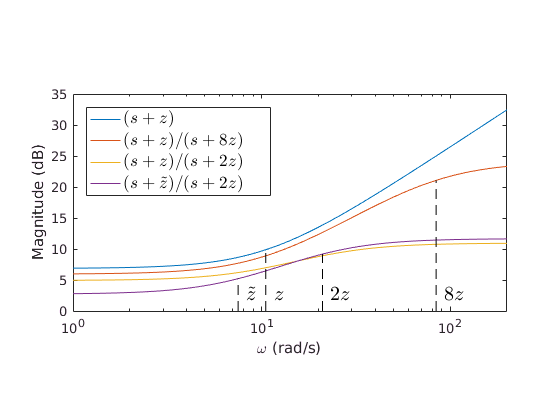

% Fig. 6.18: Frequency response of controllers
figure()
w = logspace(0,2.3,100);

[magPD,phasePD] = bode(ctrPD, w);
[magPDP8,phasePDP8] = bode(ctrPDP8, w);
[magPDP2,phasePDP2] = bode(ctrPDP2, w);
[maglead,phaselead] = bode(Clead, w);

[wlPD,maglPD,wpPD,phslPD] = basym(ctrPD);
[wlPDP8,maglPDP8,wpPDP8,phslPDP8] = basym(ctrPDP8);
[wlPDP2,maglPDP2,wpPDP2,phslPDP2] = basym(ctrPDP2);
[wllead,magllead,wplead,phsllead] = basym(Clead);

maglPD(2) = 20*log10(abs(freqresp(ctrPD,wlPD(2))));
maglPDP8(3) = 20*log10(abs(freqresp(ctrPDP8,wlPDP8(3))));
magllead(2) = 20*log10(abs(freqresp(Clead,wllead(2))));
magllead(3) = 20*log10(abs(freqresp(Clead,wllead(3))));

semilogx(w, 20*log10([magPD(:)'; magPDP8(:)'; magPDP2(:)'; maglead(:)']), ...
         [wlPD(2) wlPD(2)], [0 maglPD(2)], 'k--', ...
         [wlPDP8(3) wlPDP8(3)], [0 maglPDP8(3)], 'k--', ...
         [wllead(2) wllead(2)], [0 magllead(2)], 'k--', ...
         [wllead(3) wllead(3)], [0 magllead(3)], 'k--');
xlim(10.^[0 2.3]);
pbaspect([1 1/2 1]);

text(1.1*wlPD(2), 2.5, '$z$','interpreter','latex','FontSize',15,'HorizontalAlignment','left');

text(1.1*wlPDP8(3), 2.5, '$8 z$','interpreter','latex','FontSize',15,'HorizontalAlignment','left');

text(1.1*wllead(2), 2.5, '$\tilde{z}$','interpreter','latex','FontSize',15,'HorizontalAlignment','left');

text(1.1*wllead(3), 2.5, '$2 z$','interpreter','latex','FontSize',15,'HorizontalAlignment','left');

legfnt = 13;
h = legend('$(s + z)$', '$(s + z)/(s + 8 z)$~~~~', '$(s + z)/(s + 2 z)$~~~~', '$(s + \tilde{z})/(s + 2 z)$~~~~', 'Location', 'NorthWest');
set(h, 'interpreter', 'latex', 'FontSize', legfnt);
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

In order to add integral action, calculate the transfer-function from $w$ to $e$ in Fig. 6.21:

D = feedback(Gpi,Clead)


D =
 
             96.67 s + 2030
  -------------------------------------
  1.45 s^3 + 30.45 s^2 + 299.4 s + 1286
 
Continuous-time transfer function.



and construct the loop transfer-function

ctrI = 1.197 * tf(1,[1 0])


ctrI =
 
  1.197
  -----
    s
 
Continuous-time transfer function.



L = ctrI * D


L =
 
               115.7 s + 2430
  -----------------------------------------
  1.45 s^4 + 30.45 s^3 + 299.4 s^2 + 1286 s
 
Continuous-time transfer function.



The gain will place the poles at the desired location, which has a double real pole, under unit feedback.

H = feedback(L,1)


H =
 
                   115.7 s + 2430
  ------------------------------------------------
  1.45 s^4 + 30.45 s^3 + 299.4 s^2 + 1402 s + 2430
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.73e+00 + 7.17e-02i     1.00e+00       4.73e+00         2.12e-01    
 -4.73e+00 - 7.17e-02i     1.00e+00       4.73e+00         2.12e-01    
 -5.77e+00 + 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    
 -5.77e+00 - 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    


The alternative design discussed in Section 6.5 corresponds to

Halt = feedback(2.3392*L,1)


Halt =
 
                   270.7 s + 5684
  ------------------------------------------------
  1.45 s^4 + 30.45 s^3 + 299.4 s^2 + 1557 s + 5684
 
Continuous-time transfer function.



damp(Halt)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.02e+00 + 5.99e+00i     3.19e-01       6.32e+00         4.96e-01    
 -2.02e+00 - 5.99e+00i     3.19e-01       6.32e+00         4.96e-01    
 -8.48e+00 + 5.11e+00i     8.57e-01       9.90e+00         1.18e-01    
 -8.48e+00 - 5.11e+00i     8.57e-01       9.90e+00         1.18e-01    


which places two poles with $\omega_n \approx 9.9$ under unity feedback displays much less damping, as seen in the root-locus diagram below:

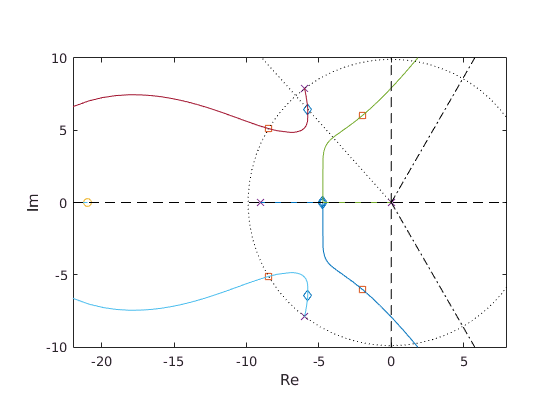

% Fig: 6.22:
figure()

pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

[wncl,zetacl,pz{3}] = damp(H);
[wnclalt,zetaclalt,pz{4}] = damp(Halt);

rl = rlocus(L);

a = (sum(pz{1}) - sum(pz{2}))/(3-1); % center of the asymptotes

t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

xl = [-22,8];
yl = [-10,10];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{4}), imag(pz{4}), 's', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), '-', ...
     [a a+10], [0 10*tan(pi/3)], 'k-.', ...
     [a a+10], [0 -10*tan(pi/3)], 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(3)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

The complete controller has transfer-function:

C6 = ctrI + Clead


C6 =
 
  5.557 s^2 + 43.41 s + 36.45
  ---------------------------
      1.45 s^2 + 30.45 s
 
Continuous-time transfer function.



zpk(C6)


ans =
 
  3.8321 (s+6.856) (s+0.9568)
  ---------------------------
           s (s+21)
 
Continuous-time zero/pole/gain model.



With the loop transfer-function:

L = C6*Gpi


L =
 
          370.4 s^2 + 2894 s + 2430
  -----------------------------------------
  1.45 s^4 + 30.45 s^3 - 71.05 s^2 - 1492 s
 
Continuous-time transfer function.



the closed-loop figures are:

H = feedback(L,1)


H =
 
             370.4 s^2 + 2894 s + 2430
  ------------------------------------------------
  1.45 s^4 + 30.45 s^3 + 299.4 s^2 + 1402 s + 2430
 
Continuous-time transfer function.



damp(H)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.73e+00 + 7.17e-02i     1.00e+00       4.73e+00         2.12e-01    
 -4.73e+00 - 7.17e-02i     1.00e+00       4.73e+00         2.12e-01    
 -5.77e+00 + 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    
 -5.77e+00 - 6.45e+00i     6.67e-01       8.66e+00         1.73e-01    


The alternative root-locus from Fig. 6.24 is plotted below:

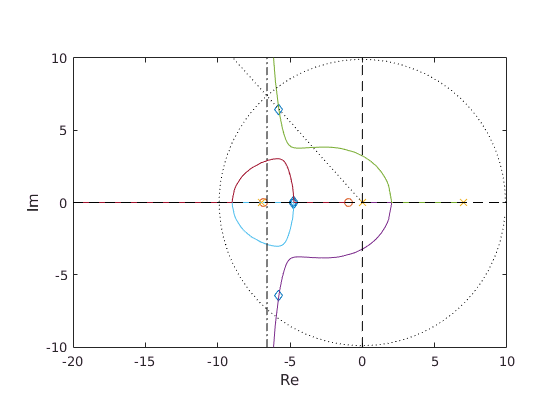

% Fig: 6.23: Complete controller root-locus
figure()

pz = {};
pz{1} = pole(L);
pz{2} = zero(L);

[wncl,zetacl,pz{3}] = damp(H);

rl = rlocus(L);

a = (sum(pz{1}) - sum(pz{2}))/(length(pz{1})-length(pz{2})); % center of the asymptotes

t = 0 : 0.1 : 2*pi;
circ = wn*cos(t) + j*wn*sin(t);

xl = [-20,10];
yl = [-10,10];

plot(real(pz{3}), imag(pz{3}), 'd', ...
     real(pz{2}), imag(pz{2}), 'o', ...
     real(pz{1}), imag(pz{1}), 'x', ...
     real(rl'), imag(rl'), '-', ...
     a*[1 1], yl, 'k-.', ...
     real(circ), imag(circ), 'k:', ...
     [0 yl(1)], [0 yl(2)/tan(asin(zetacl(3)))], 'k:', ...
     xl, [0 0], 'k--', ...
     [0 0], yl, 'k--')

xlabel('Re')
ylabel('Im')
xlim(xl)
ylim(yl)
set(gca, 'PlotBoxAspectRatio', [1 diff(yl)/diff(xl) 1]);

Compare the frequency-response of the lead controller with the final controller that has integral action:

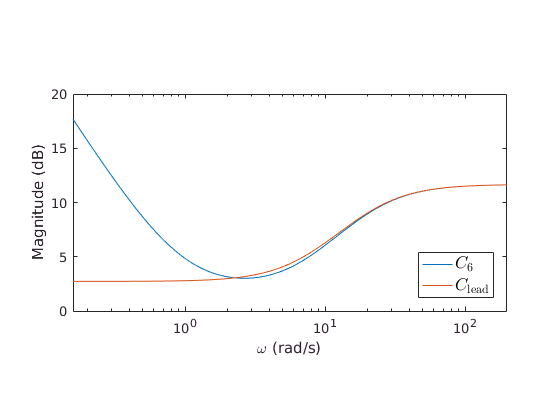

% Fig. 6.23:
figure()
w = logspace(-.8,2.3,100);
[maglead,phaselead] = bode(Clead, w);
[magC6,phaseC6] = bode(C6, w);

[wllead,magllead,wplead,phsllead] = basym(Clead);
[wlC6,maglC6,wpC6,phsC6] = basym(C6);

figure(10),clf

semilogx(w, 20*log10([magC6(:)'; maglead(:)']));
xlim(10.^[-.8 2.3]);
pbaspect([1 1/2 1]);

l = legend('$C_6$~', '$C_\mathrm{lead}$', 'Location','SouthEast');
set(l, 'interpreter', 'latex', 'FontSize', legfnt);
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');